clear all;
close all;
load("../step004-identify-transfer-function/matlab/identifyTransferFunctionContinuousTimeResults.mat");
delta_t= identifyTransferFunctionContinuousTimeResults.delta_t; 
uStep= identifyTransferFunctionContinuousTimeResults.uStep; 
tData= identifyTransferFunctionContinuousTimeResults.tData;
yDeg= identifyTransferFunctionContinuousTimeResults.yData;

GS= identifyTransferFunctionContinuousTimeResults.continuousTimeTransferFunction;
GS

GS =
  From input "u1" to output "y1":
          8496
  --------------------
  s^2 + 21.99 s + 7797
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                               
Estimated using TFEST on time domain data "identData".
Fit to estimation data: 88.06%                        
FPE: 0.02961, MSE: 0.02682                            
 
Model Properties


Convert the continuous-time transfer function to a discrete-time state model, still in frequency space, with sampling time delta_t:

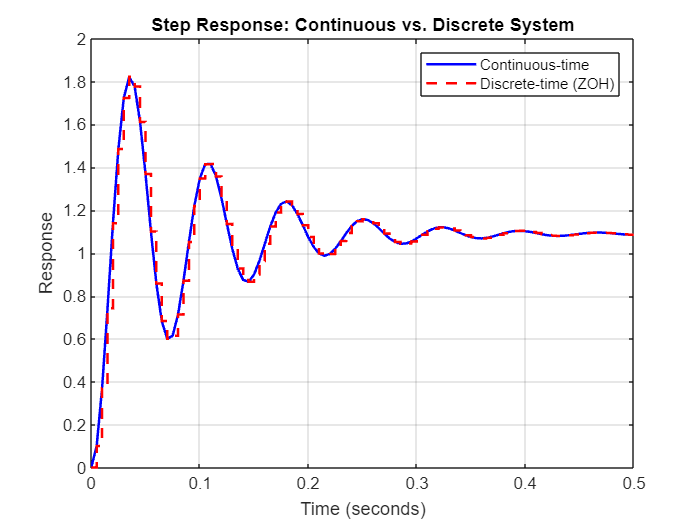

% Define the sample time
Ts = 0.005; % s

% Discretize the system using Zero-Order Hold (ZOH)
% TODO: check for exact time discretization
GS_d = c2d(GS, Ts, 'zoh');

% Create time vectors
t_cont = 0:Ts:0.5;   % Time vector for continuous-time response
t_disc = 0:Ts:0.5;   % Time vector for discrete-time response

% Compute step responses
[y_cont, t_cont] = step(GS, t_cont);      % Continuous-time step response
[y_disc, t_disc] = step(GS_d, t_disc);    % Discrete-time step response

% Plot both responses
figure;
plot(t_cont, y_cont, 'b-', 'LineWidth', 1.5); hold on;
stairs(t_disc, y_disc, 'r--', 'LineWidth', 1.5);  % Use stairs for discrete system
grid on;
xlabel('Time (seconds)');
ylabel('Response');
title('Step Response: Continuous vs. Discrete System');
legend('Continuous-time', 'Discrete-time (ZOH)');

Convert to state space, design LQR and plot closed-loop step response:

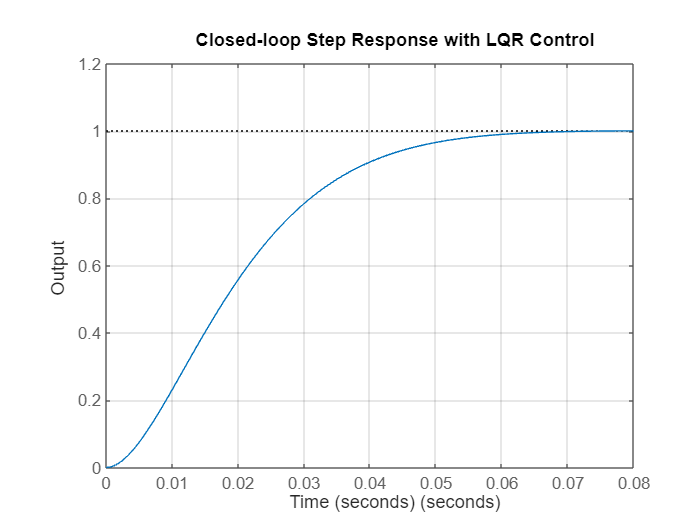

% Convert to state-space
sys_ss = ss(GS);

% Design LQR controller
% Choose weighting matrices (tune Q and R)
%Q = eye(size(sys_ss.A));      % State weighting
Q= diag([100, 1]); 
R = 1;                        % Input weighting
K = lqr(sys_ss, Q, R);        % Compute optimal gain

% Compute reference gain (for step tracking)
% Assumes full-state feedback and unity output
Nbar = -1 / (sys_ss.C * inv(sys_ss.A - sys_ss.B*K) * sys_ss.B);

% Closed-loop system with reference input r(t)
A_cl = sys_ss.A - sys_ss.B * K;
B_cl = sys_ss.B * Nbar;        % Scaled to track reference
C_cl = sys_ss.C;
D_cl = sys_ss.D;

sys_cl = ss(A_cl, B_cl, C_cl, D_cl);

% Simulate step response
figure;
step(sys_cl)
title('Closed-loop Step Response with LQR Control')
xlabel('Time (seconds)')
ylabel('Output')
grid on;